## ECE 113DA/DB/DW Capstone MATLAB Script

clear;
Fs= 8e3; %default sampling rate

%
% Example code to store store samples from bin file into MATLAB
%
% Creating other non human sounds for analysis
tone=sin(1000*pi*[1:4000]/4000)';
sweep=sin(pi*[1:4000].*[1:4000]/8000)';
noise=randn(4000,1);

T = 2; %sample length in seconds
word1 = recordAudio(T);

Start speaking.
End of Recording.


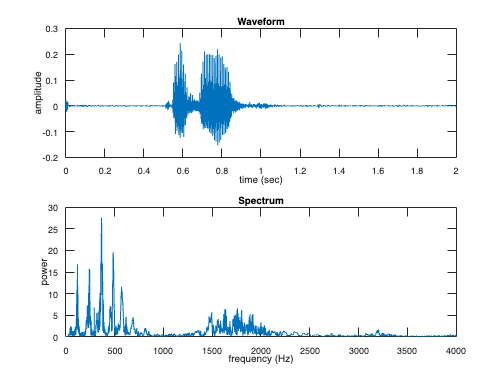

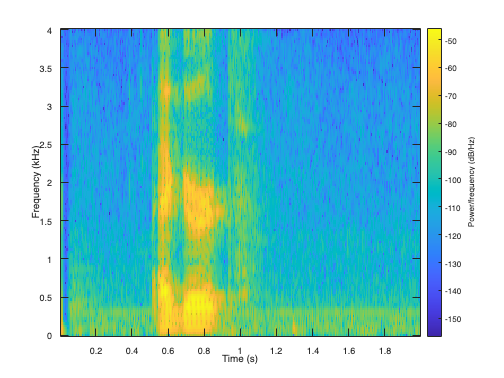

[f,Y] = spectrum(word1, T);

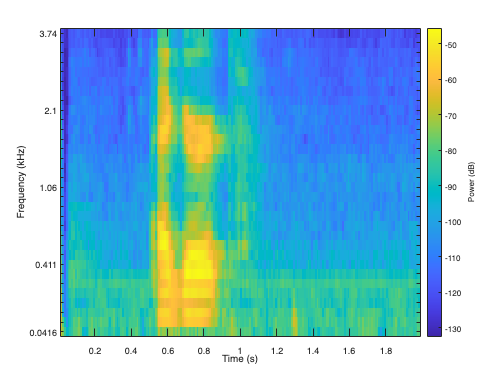

[S,cF,t] = melSpectrogram(word1,Fs);
melSpectrogram(word1,Fs)

%CODE TO RECORD AUDIO, CREDIT: FLAVIO LORENZELI'S ECE 114

T = 2; %sample length in seconds
word2 = recordAudio(T);

Start speaking.
End of Recording.


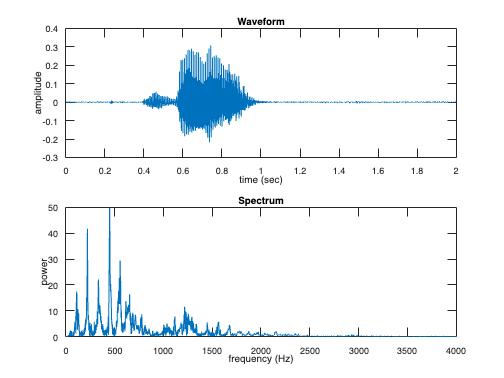

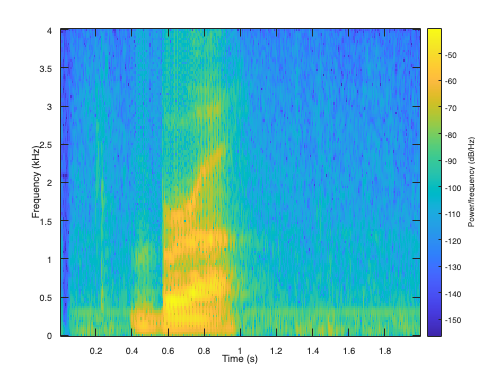

[f,Y] = spectrum(word2, T);

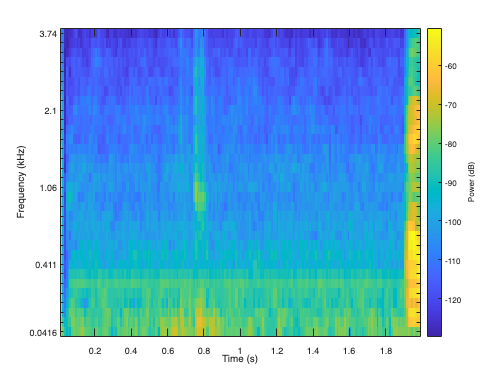

[S,cF,t] = melSpectrogram(word2,Fs);
melSpectrogram(word3,Fs)

T = 2; %sample length in seconds
word3 = recordAudio(T);

Start speaking.
End of Recording.


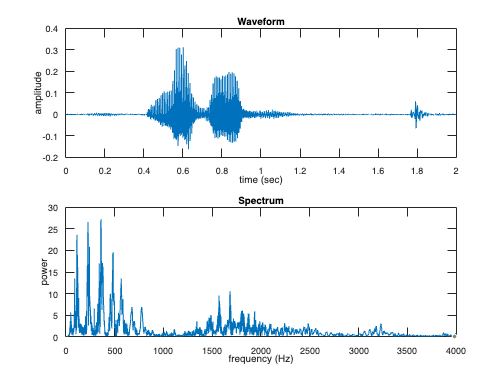

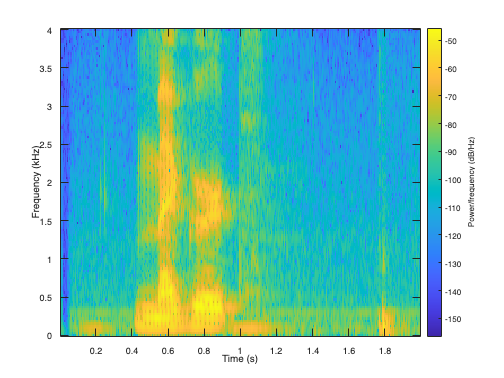

[f,Y] = spectrum(word3, T);

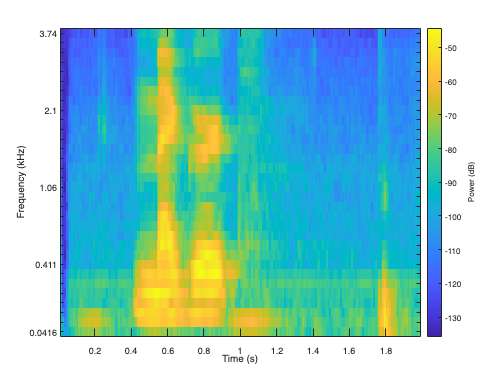

[S,cF,t] = melSpectrogram(word3,Fs);
melSpectrogram(word3,Fs)

soundsc(word3, Fs) %playback audio


The following code is to define a MATLAB CNN that acts on the "image" that is the spectrogram or the mel frequency spetrum

%Code below is a generic CNN for now, no attention paid to the model
%definiation or even the shape, just the syntax

layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];


function recording = recordAudio(T) %takes in time in seconds
    Fs = 8e3;
    %if your computer has a microphone, use this block
    recObj = audiorecorder(Fs, 16, 1);
    disp('Start speaking.')
    recordblocking(recObj,T);
    disp('End of Recording.');
    recording = getaudiodata(recObj); %% variable that saves audio
    soundsc(recording, Fs);
end

%alternate:

%[rec, Fs]=audioread('my_voice.wav') %or my_voice.mp3;
%T=length(rec)/Fs;


function [f,Y] = spectrum(rec, T)
    Fs = 8e3;
    t=[1:numel(rec)]/Fs;
    freq=abs((fft(rec)));
    Y = freq(1:length(freq)/2+1);
    f=[0:length(Y)-1]/T;
    % Plot the waveform and spectrum.
    figure()
    subplot(2,1,1)
    plot(t,rec,'')
    title('Waveform')
    xlabel('time (sec)')
    ylabel('amplitude')
    subplot(2,1,2)
    plot(f,Y);
    title('Spectrum')
    xlabel('frequency (Hz)')
    ylabel('power')
    figure()
    spectrogram(rec,100,[],[],Fs,'yaxis');
    colormap default %you can choose your favorite color scheme ;)
end


